# A brief tutorial on linear time warping, a.k.a. "time normalization"

Linear time warping, also known as "time normalization", is a simple method for rescaling the temporal coordinate of a signal.

#### Input

There are three inputs:

- (1) a signal

- (2) the time values (or indices) of the signal

- (3) the desired time indices that we will warp to

Here are the first two inputs, the signal and its time indices:

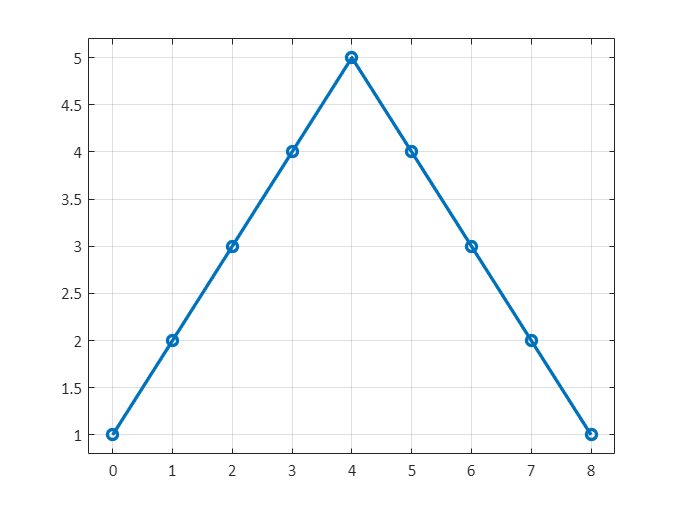

% (1) the signal:
x_orig = [1 2 3 4 5 4 3 2 1];

% (2) the time values
t_orig = [0 1 2 3 4 5 6 7 8];

fig; plot(t_orig,x_orig,'o-'); format_axes;

Note that the time indices of the original signal are evenly spaced in this example, but in general they do not need to be.

#### The linear time index re-mapping

Here are the desired time values that we will map the original ones to. Notice that these are defined as $L$equally spaced steps over a desired time range, here $[0,10]$, where $L$ is the length of the original signal.

L_orig = length(t_orig);

desired_time_range = [0 10];

t_warp = linspace(desired_time_range(1),desired_time_range(2),L_orig)

t_warp =          0    1.2500    2.5000    3.7500    5.0000    6.2500    7.5000    8.7500   10.0000


This is a visual illustration of the mapping:

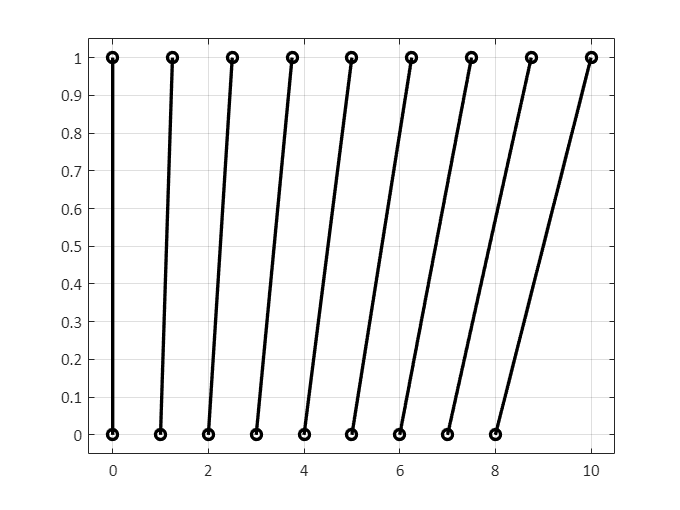

fig;
for i=1:length(t_orig)
    plot([t_orig(i) t_warp(i)],[0 1],'ko-'); hold on;
end
format_axes;

Notice that the ratio of the interval between any pair of time indices in the original to the interval between the associated indices in the warp is the same--this is the "linearity" property, e.g.:

diff(t_orig([1 2]))/diff(t_warp([1 2]))

ans = 0.8000


diff(t_orig([3 5]))/diff(t_warp([3 5]))

ans = 0.8000


diff(t_orig([1 end]))/diff(t_warp([1 end]))

ans = 0.8000

The desired time range of $[0,10]$ in the example above is arbitrary. This might be, for example, the time range of some reference signal, or the median length of signals in a set of signals.

Here is a comparison of the original and warped signals:

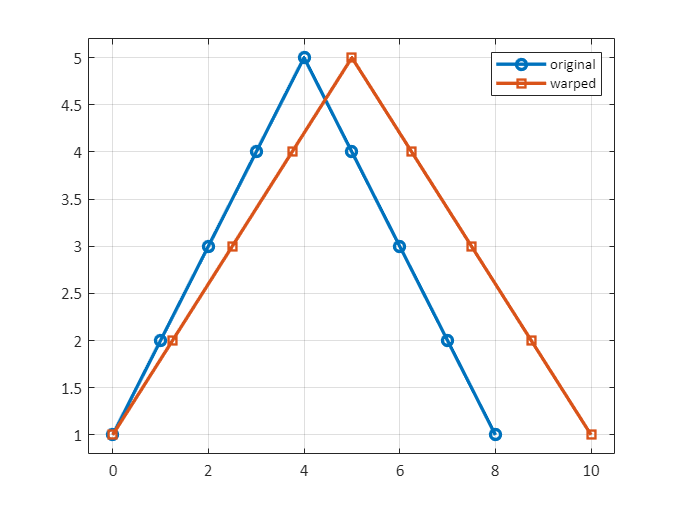

fig;
plot(t_orig,x_orig,'o-'); hold on;
plot(t_warp,x_orig,'s-');
format_axes;
legend({'original' 'warped'})

#### Resampling

Very commonly it is the case the linear time warping is conducted so that signals of different lengths can be transformed to signals of the same length, to faciliate averaging or calculation of similarity. The linear mapping step above does not accomplish this, since it preserves the length (in number of samples) of the original signal. To obtain a signal that is a desired length, a linear interpolation can be applied:

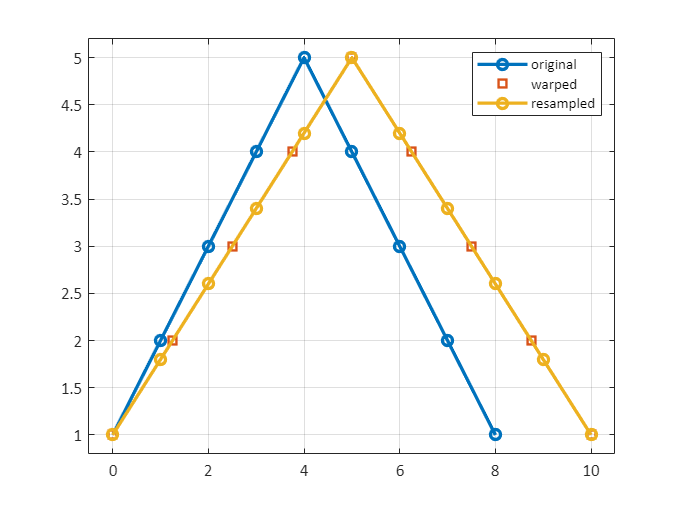

L_desired = 11;

t_interp = linspace(t_warp(1),t_warp(end),L_desired);

%
x_warped = interp1(t_warp,x_orig,t_interp,'linear');

fig;
plot(t_orig,x_orig,'o-'); hold on;
plot(t_warp,x_orig,'s'); 
plot(t_interp,x_warped,'o-');
legend({'original' 'warped' 'resampled'})
format_axes;

The time index re-mapping and resampling steps are conceptually independent, but they can be combined as follows:

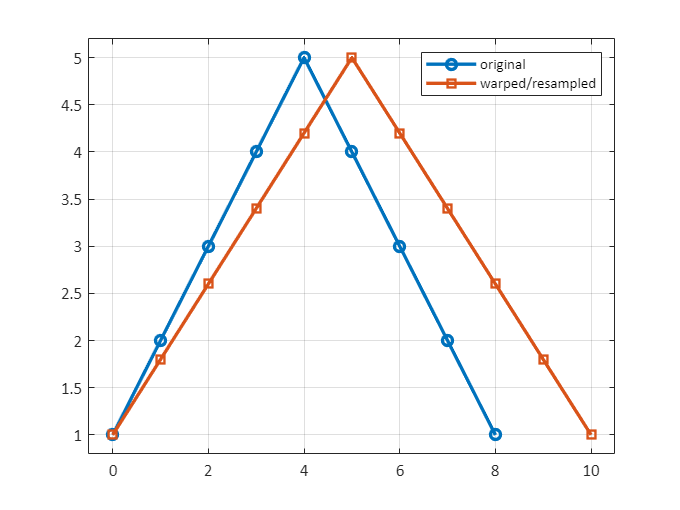

L_desired = 11;

x_warped = interp1(1:L_orig,x_orig,linspace(1,L_orig,L_desired),'linear');
t_warp = 0:L_desired-1;

fig;
plot(t_orig,x_orig,'o-'); hold on;
plot(t_warp,x_warped,'s-'); 
legend({'original' 'warped/resampled'})
format_axes;

function [] = fig()
clear all; %#ok<CLALL> 
set(0,'defaultfigureposition',[ 680   558   560   420],'defaultfigureunits','pixels');
set(0,'defaultlinelinewidth',2);
figure('units','pixels','position',[ 680   558   560   420]);
end

function [] = format_axes()
axis tight;
ylim(ylim+0.05*diff(ylim)*[-1 1]);
xlim(xlim+0.05*diff(xlim)*[-1 1]);
set(gca,'XGrid','on','YGrid','on');
end